# NeurWEM prelim fMRI -- figure panels

Regenerates every prelim panel as 300-dpi PNG (house style). Each section runs independently (Ctrl+Enter) and writes its figures to prelim_fmri/figures/. The drawing code lives in the local functions at the bottom of this notebook. N = 9 fMRI subjects (101-109); accuracy-split / MST panels drop to N = 7-8.

## Setup

here = fileparts(matlab.desktop.editor.getActiveFilename);
if isempty(here), here = pwd; end
root = fullfile(here,'..','..');
dat  = fullfile(root,'data','mstback'); datm = fullfile(root,'data','mst');
addpath(fullfile(root,'..','scripts'));
W4 = 3.3; W2 = 3.9; H = 3.8;
T  = readtable(fullfile(dat,'roi_2x2_cells.csv'));
M  = load(fullfile(datm,'m3_roi.mat'));
HT = readtable(fullfile(dat,'rsa_hyp_cells.csv'));
ST = readtable(fullfile(dat,'rsa_hyp_stats.csv'));
RT = readtable(fullfile(dat,'rsa_reinstate_hcsplit.csv'));
% ROI table for the 2x2 panels (order: MTL -> parietal -> PFC -> visual)
RO = {'HC_whole','HC_ant','Perirhinal','Angular','IPS','DLPFC','sPCS_FEF','IFG','preSMA','ACC','VentralTemporal','LOC','EarlyVisual','Visual'};
RL = {'Hippocampus','Anterior hippocampus','Perirhinal','Angular gyrus','Superior parietal (IPS)','DLPFC',...
      'Superior precentral sulcus (FEF)','Inferior frontal gyrus','Pre-SMA','Anterior cingulate',...
      'Ventral temporal','Lateral occipital','Early visual (V1/V2)','Visual cortex'};
IC = {'','roi_HCant','roi_Perirhinal','roi_Angular','roi_IPS','roi_DLPFC','','','','','roi_VentralTemporal','','','roi_Visual'};

## 1 | Behaviour: similar discrimination (index + explanatory)

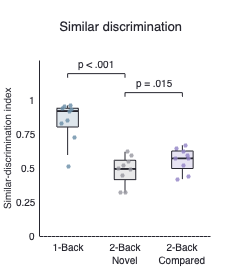

behav_combined(here,[W4 H],'di','di_one','Similar-discrimination index','Similar discrimination','fig_behav_2back');

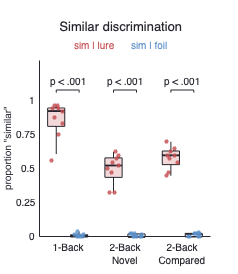

behav_explain(here,[W4 H],'hitSim','faSim','hitSim_one','faSim_one','di','di_one','proportion "similar"','Similar discrimination','fig_behav_2back_explain','sim | lure','sim | foil');

## 2 | Behaviour: same detection (index + explanatory)

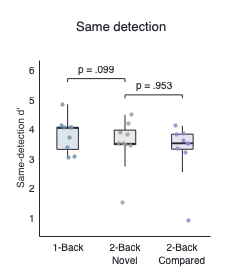

behav_combined(here,[W4 H],'dSame','dSame_one','Same-detection d''','Same detection','fig_behav_2back_same');

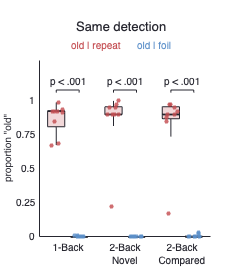

behav_explain(here,[W4 H],'hitSame','faSame','hitSame_one','faSame_one','dSame','dSame_one','proportion "old"','Same detection','fig_behav_2back_same_explain','old | repeat','old | foil');

## 3 | ROI 2x2: similar discrimination (13 ROIs)

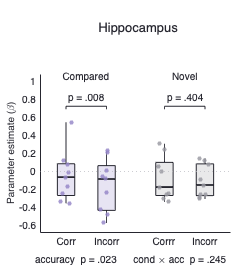

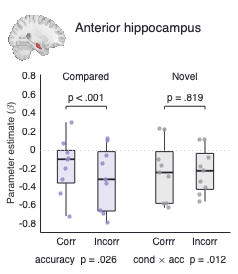

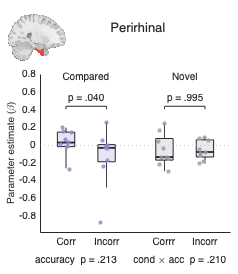

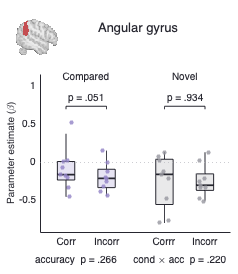

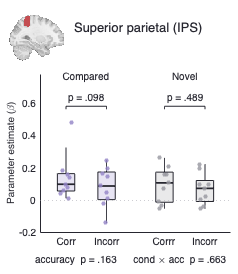

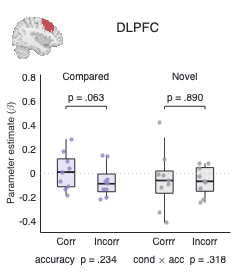

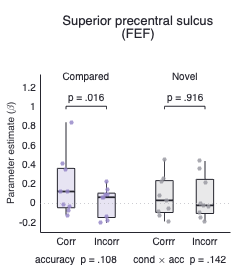

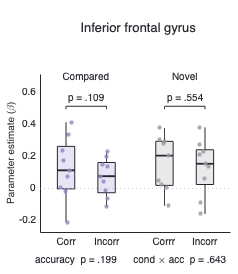

for k = 1:numel(RO)
    roi_2x2(T,here,[W4 H],RO{k},RL{k},[0 0],IC{k});
end

## 4 | ROI 2x2: same detection (13 ROIs)

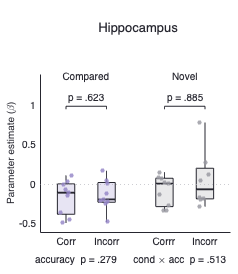

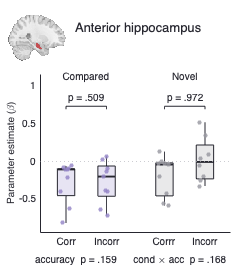

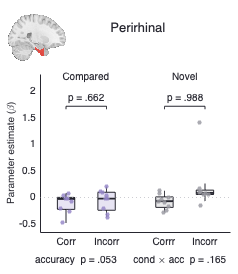

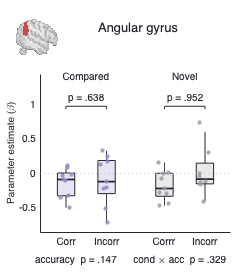

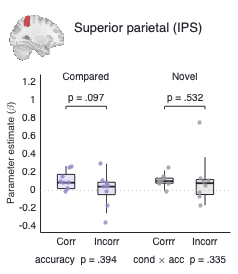

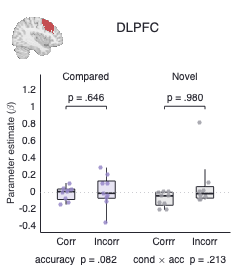

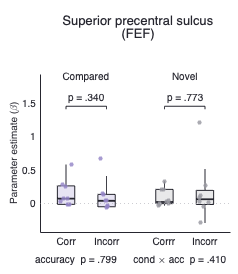

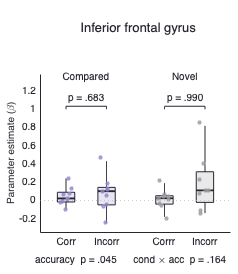

for k = 1:numel(RO)
    roi_2x2(T,here,[W4 H],RO{k},RL{k},[0 0],IC{k},'same');
end

## 5 | MST: behaviour + memory success

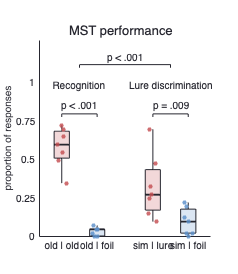

behav_mst(datm,here,[W4 H]);

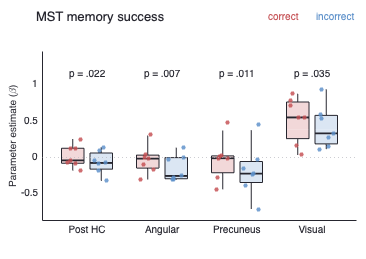

mem_strip(M,here,{'HC_post','Angular','Precuneus','Visual'},{'Post HC','Angular','Precuneus','Visual'},'mst_memory','MST memory success');

## 6 | RSA reinstatement (item-specific; one figure per similarity, ROIs share y-axis)

RROI = {'HC_ant','Perirhinal','Angular','VentralTemporal','LOC','EarlyVisual'};
RLAB = {'Ant HC','Perirhinal','Angular','Vent temp','LOC','Early visual'};
rsahyp_strip(HT,ST,here,RROI,RLAB,'completion','compared','b2b1','B2-B1 neural similarity');
rsahyp_strip(HT,ST,here,RROI,RLAB,'separation','compared','b1a1','A1-B1 neural similarity');
rsahyp_strip(HT,ST,here,RROI,RLAB,'predictive','compared','a2b1','A2-B1 neural similarity');
rsahyp_strip(HT,ST,here,RROI,RLAB,'wm_discrim','compared','a2b2_Compared','A2-B2 neural similarity (Compared)');
rsahyp_strip(HT,ST,here,RROI,RLAB,'wm_discrim','novel','a2b2_Novel','A2-B2 neural similarity (Novel)');

## 7 | Anterior-HC -- cortex reinstatement coupling (B2-B1, trial-wise)

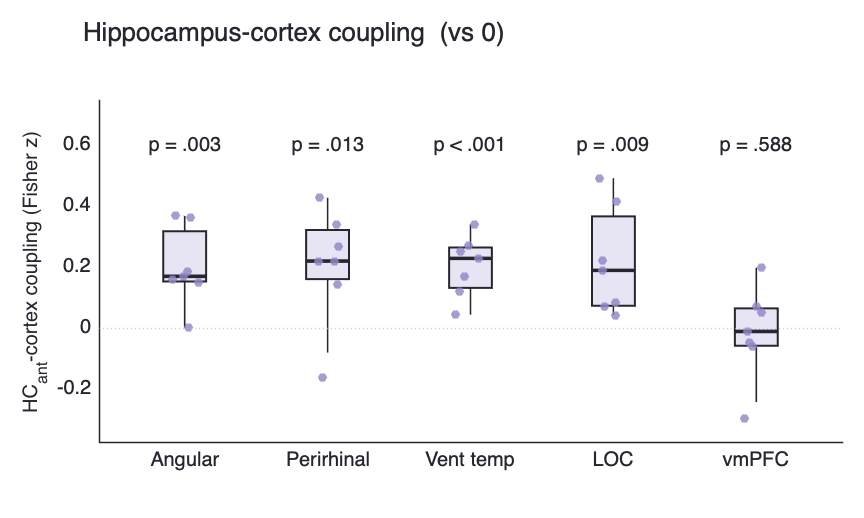

CROI = {'Angular','Perirhinal','VentralTemporal','LOC','vmPFC'};
CLAB = {'Angular','Perirhinal','Vent temp','LOC','vmPFC'};
rsa_couple0(RT,here,'HC_ant',CROI,CLAB,'coupling_hcant_vs0','Hippocampus-cortex coupling');

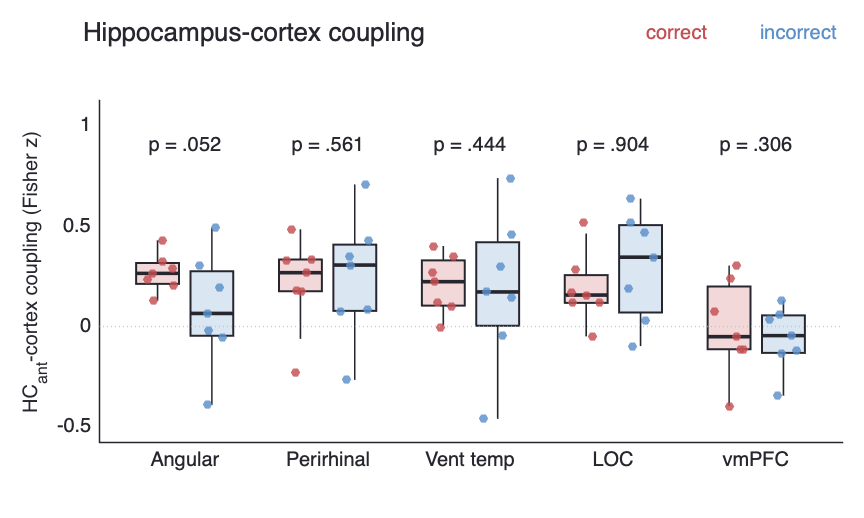

rsa_couple(RT,here,'HC_ant',CROI,CLAB,'coupling_hcant','Hippocampus-cortex coupling');

## Local functions (drawing code)

function roi_2x2(T,here,SZ,roi,roilab,tails,icon,pre)
if nargin<8, pre='sim'; end
INK=[0.149 0.149 0.184]; PUR=[0.58 0.52 0.78]; GRY=[0.60 0.60 0.63];
s=unique(T.subj); g=@(c)arrayfun(@(x)getv(T,x,roi,c),s);
cc=g([pre '_cmp_hit']); ci=g([pre '_cmp_miss']); nc=g([pre '_nov_hit']); ni=g([pre '_nov_miss']);
x=[1 1.7 2.7 3.4]; D={cc,ci,nc,ni}; C=[PUR;PUR;GRY;GRY];
[f,ax]=canvas(here,SZ,icon,roilab);
for k=1:4, boxdot(ax,x(k),D{k},C(k,:),INK); end
yline(ax,0,':','Color',[0.72 0.72 0.75],'LineWidth',0.8);
allv=cell2mat(D(:)); ymax=max(allv,[],'omitnan'); ymin=min(allv,[],'omitnan'); yr=ymax-ymin;
yb=ymax+0.16*yr;
[pa,pint,pc,pn]=lmep(cc,ci,nc,ni);   % mixed-model (fitlme): main effects + one-tailed simple effects
brklab(ax,x(1),x(2),yb,yr,pc,'Compared',INK);
brklab(ax,x(3),x(4),yb,yr,pn,'Novel',INK);
annotation(f,'textbox',[0.03 0.02 0.94 0.055],'String',sprintf('accuracy  %s      cond \\times acc  %s',pp(pa),pp(pint)),'EdgeColor','none','HorizontalAlignment','right','VerticalAlignment','middle','FontName','Helvetica','FontSize',10,'Color',INK);
ax.XTick=x; ax.XTickLabel={'Corr','Incorr','Corrr','Incorr'}; ax.XTickLabelRotation=0; ax.XAxis.FontSize=10;
xlim(ax,[0.55 3.85]); ylim(ax,[ymin-0.10*yr ymax+0.48*yr]);
ylabel(ax,'Parameter estimate (\beta)','FontName','Helvetica','FontSize',10);
place_icon(f,ax,here,icon);
fn='fig_2x2'; if ~strcmp(pre,'sim'), fn=['fig_2x2' pre]; end
finish(ax,INK); exportgraphics(f,fullfile(here,'..','..','figures','mstback',sprintf('%s_%s.png',fn,lower(roi))),'Resolution',300); close(f);
end

function mem_roi(M,here,SZ,roi,roilab,icon)
INK=[0.149 0.149 0.184]; PUR=[0.58 0.52 0.78];
ec=M.([roi '_em_c'])(:); ei=M.([roi '_em_i'])(:);
[f,ax]=canvas(here,SZ,icon,roilab);
boxdot(ax,1,ec,PUR,INK); boxdot(ax,2,ei,PUR,INK);
yline(ax,0,':','Color',[0.72 0.72 0.75],'LineWidth',0.8);
allv=[ec;ei]; ymax=max(allv); ymin=min(allv); yr=ymax-ymin;
brklab(ax,1,2,ymax+0.12*yr,yr,lmep2(ec,ei,1),'',INK);
tk=niceticks(ymin,ymax,5);
ax.XTick=[1 2]; ax.XTickLabel={'Correct','Incorrect'}; ax.YTick=tk; ax.XTickLabelRotation=0;
xlim(ax,[0.4 2.6]); ylim(ax,[min(ymin,tk(1))-0.06*yr max(ymax+0.26*yr,tk(end)+0.01*yr)]);
ylabel(ax,'Parameter estimate (\beta)','FontName','Helvetica','FontSize',10);
place_icon(f,ax,here,icon);
finish(ax,INK); exportgraphics(f,fullfile(here,'..','..','figures','mst',sprintf('fig_mem_%s.png',lower(roi))),'Resolution',300); close(f);
end

function mem_strip(M,here,ROI,LAB,tag,ylab)
% MST memory success: all ROIs in one panel (RSA-strip format), correct vs incorrect
INK=[0.149 0.149 0.184]; TARG=[0.768 0.306 0.321]; FOIL=[0.357 0.561 0.788];
nR=numel(ROI); W=1.4+0.92*nR; Hh=3.6;
f=figure('Color','w','Units','inches','Position',[1 1 W Hh]);
annotation(f,'textbox',[0.085 0.885 0.62 0.09],'String',ylab,'EdgeColor','none','HorizontalAlignment','left','VerticalAlignment','middle','FontName','Helvetica','FontSize',13,'Color',INK);
annotation(f,'textbox',[0.70 0.885 0.13 0.09],'String','correct','EdgeColor','none','HorizontalAlignment','right','VerticalAlignment','middle','FontName','Helvetica','FontSize',10,'Color',TARG);
annotation(f,'textbox',[0.83 0.885 0.15 0.09],'String','incorrect','EdgeColor','none','HorizontalAlignment','right','VerticalAlignment','middle','FontName','Helvetica','FontSize',10,'Color',FOIL);
ax=axes(f,'Position',[0.115 0.145 0.86 0.66]); hold(ax,'on'); set(ax,'FontName','Helvetica','FontSize',10);
allv=[];
for k=1:nR
    ec=M.([ROI{k} '_em_c'])(:); ei=M.([ROI{k} '_em_i'])(:);
    boxdot(ax,k-0.19,ec,TARG,INK); boxdot(ax,k+0.19,ei,FOIL,INK); allv=[allv;ec;ei];
end
yline(ax,0,':','Color',[0.72 0.72 0.75],'LineWidth',0.8);
ymax=max(allv,[],'omitnan'); ymin=min(allv,[],'omitnan'); yr=ymax-ymin;
for k=1:nR
    ec=M.([ROI{k} '_em_c'])(:); ei=M.([ROI{k} '_em_i'])(:);
    text(ax,k,ymax+0.09*yr,pp(lmep2(ec,ei,1)),'HorizontalAlignment','center','VerticalAlignment','bottom','FontName','Helvetica','FontSize',10,'Color',INK);
end
ax.XTick=1:nR; ax.XTickLabel=LAB; ax.XTickLabelRotation=0;
xlim(ax,[0.4 nR+0.6]); ylim(ax,[min(ymin,0)-0.10*yr ymax+0.32*yr]);
ylabel(ax,'Parameter estimate (\beta)','FontName','Helvetica','FontSize',10);
finish(ax,INK); exportgraphics(f,fullfile(here,'..','..','figures','mst',sprintf('fig_%s.png',tag)),'Resolution',300); close(f);
end

function rsahyp_strip(HT,ST,here,ROI,LAB,contr,cond,tag,ylab)
INK=[0.149 0.149 0.184]; TARG=[0.768 0.306 0.321]; FOIL=[0.357 0.561 0.788];
nR=numel(ROI); W=1.4+0.92*nR; Hh=3.6;
f=figure('Color','w','Units','inches','Position',[1 1 W Hh]);
annotation(f,'textbox',[0.085 0.885 0.62 0.09],'String',ylab,'EdgeColor','none','HorizontalAlignment','left','VerticalAlignment','middle','FontName','Helvetica','FontSize',13,'Color',INK);
annotation(f,'textbox',[0.70 0.885 0.13 0.09],'String','correct','EdgeColor','none','HorizontalAlignment','right','VerticalAlignment','middle','FontName','Helvetica','FontSize',10,'Color',TARG);
annotation(f,'textbox',[0.83 0.885 0.15 0.09],'String','incorrect','EdgeColor','none','HorizontalAlignment','right','VerticalAlignment','middle','FontName','Helvetica','FontSize',10,'Color',FOIL);
ax=axes(f,'Position',[0.115 0.145 0.86 0.66]); hold(ax,'on'); set(ax,'FontName','Helvetica','FontSize',10);
allv=[];
for k=1:nR
    cc=getH(HT,ROI{k},contr,cond,'correct'); ci=getH(HT,ROI{k},contr,cond,'incorrect');
    boxdot(ax,k-0.19,cc,TARG,INK); boxdot(ax,k+0.19,ci,FOIL,INK); allv=[allv;cc;ci];
end
yline(ax,0,':','Color',[0.72 0.72 0.75],'LineWidth',0.8);
av=allv(isfinite(allv)); ymax=prctile(av,98); ymin=prctile(av,2); yr=ymax-ymin;
for k=1:nR
    p=getp(ST,ROI{k},contr,cond);
    if ~isnan(p), text(ax,k,ymax+0.09*yr,pp(p),'HorizontalAlignment','center','VerticalAlignment','bottom','FontName','Helvetica','FontSize',10,'Color',INK); end
end
ax.XTick=1:nR; ax.XTickLabel=LAB; ax.XTickLabelRotation=0;
xlim(ax,[0.4 nR+0.6]); ylim(ax,[ymin-0.10*yr ymax+0.32*yr]);
ylabel(ax,'Neural pattern-similarity (Fisher z)','FontName','Helvetica','FontSize',10);
finish(ax,INK); exportgraphics(f,fullfile(here,'..','..','figures','mstback',sprintf('fig_rsa_%s.png',tag)),'Resolution',300); close(f);
end

function rsa_couple(RT,here,seed,CROI,CLAB,tag,ttl)
INK=[0.149 0.149 0.184]; TARG=[0.768 0.306 0.321]; FOIL=[0.357 0.561 0.788];
subs=unique(RT.subj); nR=numel(CROI); ZC=nan(numel(subs),nR); ZI=nan(numel(subs),nR);
for si=1:numel(subs)
    hm=RT.subj==subs(si)&strcmp(RT.roi,seed)&strcmp(RT.cell,'B2-B1_PC'); hv=RT.sim(hm); hf=RT.correct(hm);
    for k=1:nR
        cm=RT.subj==subs(si)&strcmp(RT.roi,CROI{k})&strcmp(RT.cell,'B2-B1_PC'); cv=RT.sim(cm);
        if numel(cv)~=numel(hv), continue; end
        for a=[1 0]
            sel=hf==a&isfinite(hv)&isfinite(cv);
            if sum(sel)>=5 && std(hv(sel))>0 && std(cv(sel))>0
                z=atanh(min(max(corr(hv(sel),cv(sel)),-0.9999),0.9999));
                if a==1, ZC(si,k)=z; else, ZI(si,k)=z; end
            end
        end
    end
end
W=1.4+0.92*nR; Hh=3.6; f=figure('Color','w','Units','inches','Position',[1 1 W Hh]);
annotation(f,'textbox',[0.085 0.885 0.60 0.09],'String',ttl,'EdgeColor','none','HorizontalAlignment','left','VerticalAlignment','middle','FontName','Helvetica','FontSize',13,'Color',INK);
annotation(f,'textbox',[0.70 0.885 0.13 0.09],'String','correct','EdgeColor','none','HorizontalAlignment','right','VerticalAlignment','middle','FontName','Helvetica','FontSize',10,'Color',TARG);
annotation(f,'textbox',[0.83 0.885 0.15 0.09],'String','incorrect','EdgeColor','none','HorizontalAlignment','right','VerticalAlignment','middle','FontName','Helvetica','FontSize',10,'Color',FOIL);
ax=axes(f,'Position',[0.115 0.145 0.86 0.66]); hold(ax,'on'); set(ax,'FontName','Helvetica','FontSize',10);
for k=1:nR, boxdot(ax,k-0.19,ZC(:,k),TARG,INK); boxdot(ax,k+0.19,ZI(:,k),FOIL,INK); end
yline(ax,0,':','Color',[0.72 0.72 0.75],'LineWidth',0.8);
allv=[ZC(:);ZI(:)]; ymax=max(allv,[],'omitnan'); ymin=min(allv,[],'omitnan'); yr=ymax-ymin;
for k=1:nR
    p=lmep2(ZC(:,k),ZI(:,k),1);
    text(ax,k,ymax+0.09*yr,pp(p),'HorizontalAlignment','center','VerticalAlignment','bottom','FontName','Helvetica','FontSize',10,'Color',INK);
end
ax.XTick=1:nR; ax.XTickLabel=CLAB; ax.XTickLabelRotation=0;
xlim(ax,[0.4 nR+0.6]); ylim(ax,[ymin-0.10*yr ymax+0.32*yr]);
ylabel(ax,'HC_{ant}-cortex coupling (Fisher z)','FontName','Helvetica','FontSize',10);
finish(ax,INK); exportgraphics(f,fullfile(here,'..','..','figures','mstback',sprintf('fig_rsa_%s.png',tag)),'Resolution',300); close(f);
end

function rsa_couple0(RT,here,seed,CROI,CLAB,tag,ttl)
INK=[0.149 0.149 0.184]; PUR=[0.58 0.52 0.78];
subs=unique(RT.subj); nR=numel(CROI); ZA=nan(numel(subs),nR);
for si=1:numel(subs)
    hm=RT.subj==subs(si)&strcmp(RT.roi,seed)&strcmp(RT.cell,'B2-B1_PC'); hv=RT.sim(hm);
    for k=1:nR
        cm=RT.subj==subs(si)&strcmp(RT.roi,CROI{k})&strcmp(RT.cell,'B2-B1_PC'); cv=RT.sim(cm);
        if numel(cv)~=numel(hv), continue; end
        sel=isfinite(hv)&isfinite(cv);
        if sum(sel)>=5 && std(hv(sel))>0 && std(cv(sel))>0
            ZA(si,k)=atanh(min(max(corr(hv(sel),cv(sel)),-0.9999),0.9999));
        end
    end
end
W=1.4+0.92*nR; Hh=3.6; f=figure('Color','w','Units','inches','Position',[1 1 W Hh]);
annotation(f,'textbox',[0.085 0.885 0.80 0.09],'String',[ttl '  (vs 0)'],'EdgeColor','none','HorizontalAlignment','left','VerticalAlignment','middle','FontName','Helvetica','FontSize',13,'Color',INK);
ax=axes(f,'Position',[0.115 0.145 0.86 0.66]); hold(ax,'on'); set(ax,'FontName','Helvetica','FontSize',10);
for k=1:nR, boxdot(ax,k,ZA(:,k),PUR,INK); end
yline(ax,0,':','Color',[0.72 0.72 0.75],'LineWidth',0.8);
allv=ZA(:); ymax=max(allv,[],'omitnan'); ymin=min(allv,[],'omitnan'); yr=ymax-ymin;
for k=1:nR
    v=ZA(:,k); v=v(isfinite(v)); if numel(v)<2, continue; end
    [~,p]=ttest(v,0,'Tail','right');
    text(ax,k,ymax+0.09*yr,pp(p),'HorizontalAlignment','center','VerticalAlignment','bottom','FontName','Helvetica','FontSize',10,'Color',INK);
end
ax.XTick=1:nR; ax.XTickLabel=CLAB; ax.XTickLabelRotation=0;
xlim(ax,[0.4 nR+0.6]); ylim(ax,[ymin-0.10*yr ymax+0.32*yr]);
ylabel(ax,'HC_{ant}-cortex coupling (Fisher z)','FontName','Helvetica','FontSize',10);
finish(ax,INK); exportgraphics(f,fullfile(here,'..','..','figures','mstback',sprintf('fig_rsa_%s.png',tag)),'Resolution',300); close(f);
end

function v=getH(HT,roi,contr,cond,acc)
m=strcmp(HT.roi,roi)&strcmp(HT.contrast,contr)&strcmp(HT.condition,cond)&strcmp(HT.accuracy,acc);
v=HT.index(m);
end

function p=getp(ST,roi,contr,cond)
m=strcmp(ST.roi,roi)&strcmp(ST.contrast,contr)&strcmp(ST.condition,cond);
if any(m), p=ST.p_pred1tail(find(m,1)); else, p=NaN; end
end

function behav_explain(here,SZ,hfld,ffld,h1fld,f1fld,idxfld,idx1fld,ylab,ttl,oname,hlab,flab)
INK=[0.149 0.149 0.184]; TARG=[0.768 0.306 0.321]; FOIL=[0.357 0.561 0.788];
subs=101:109; H=nan(numel(subs),3); Fa=nan(numel(subs),3); IX=nan(numel(subs),3);
for i=1:numel(subs)
    Dc=nm_load_long(subs(i)); if isempty(Dc), continue; end; m=nm_metrics(Dc);
    H(i,:) =[m.(h1fld) m.(hfld)(1) m.(hfld)(2)];      % cols: 1-back, compared, novel
    Fa(i,:)=[m.(f1fld) m.(ffld)(1) m.(ffld)(2)];
    IX(i,:)=[m.(idx1fld) m.(idxfld)(1) m.(idxfld)(2)];
end
ord=[1 3 2]; H=H(:,ord); Fa=Fa(:,ord); IX=IX(:,ord);   % order: 1-back, novel, compared
glab={'1-Back',sprintf('2-Back\nNovel'),sprintf('2-Back\nCompared')};
f=figure('Color','w','Units','inches','Position',[1 1 SZ]);
annotation(f,'textbox',[0.08 0.865 0.86 0.065],'String',ttl,'EdgeColor','none','HorizontalAlignment','center','VerticalAlignment','middle','FontName','Helvetica','FontSize',13,'Color',INK);
annotation(f,'textbox',[0.08 0.805 0.86 0.045],'String',['\color[rgb]{0.768,0.306,0.321}' hlab '      \color[rgb]{0.357,0.561,0.788}' flab],'EdgeColor','none','Interpreter','tex','HorizontalAlignment','center','VerticalAlignment','middle','FontName','Helvetica','FontSize',10);
ax=axes(f,'Position',[0.165 0.135 0.72 0.645]); hold(ax,'on'); set(ax,'FontName','Helvetica','FontSize',10);
ctr=[1 2 3]; dx=0.2; xh=ctr-dx; xf=ctr+dx;
for k=1:3
    boxdot(ax,xh(k),H(:,k),TARG,INK); boxdot(ax,xf(k),Fa(:,k),FOIL,INK);
    idxbr(ax,xh(k),xf(k),IX(:,k),1.08,'',INK);          % index vs chance (one-tailed), bracket p
end
ax.XTick=ctr; ax.XTickLabel={}; ax.XTickLabelRotation=0;
xlim(ax,[0.5 3.5]); ylim(ax,[0 1.3]); ax.YTick=0:0.25:1;
xlab2(ax,ctr,{'1-Back','2-Back','2-Back'},{'','Novel','Compared'},INK);
ylabel(ax,ylab,'FontName','Helvetica','FontSize',10);
finish(ax,INK); exportgraphics(f,fullfile(here,'..','..','figures','mstback',[oname '.png']),'Resolution',300); close(f);
end

function behav_combined(here,SZ,fld2,fld1,ylab,ttl,oname)
INK=[0.149 0.149 0.184]; PUR=[0.58 0.52 0.78]; GRY=[0.60 0.60 0.63]; ONE=[0.42 0.56 0.66];
subs=101:109; V=nan(numel(subs),3);
for i=1:numel(subs)
    Dc=nm_load_long(subs(i)); if isempty(Dc), continue; end
    m=nm_metrics(Dc); d2=m.(fld2); V(i,:)=[m.(fld1) d2(1) d2(2)];
end
% order: 1-back, Novel, Compared   (V columns are [1-back, Compared, Novel])
x=[1 1.8 2.6]; one=V(:,1); nov=V(:,3); cmp=V(:,2);
f=figure('Color','w','Units','inches','Position',[1 1 SZ]);
annotation(f,'textbox',[0.08 0.865 0.86 0.065],'String',ttl,'EdgeColor','none','HorizontalAlignment','center','VerticalAlignment','middle','FontName','Helvetica','FontSize',13,'Color',INK);
ax=axes(f,'Position',[0.165 0.135 0.72 0.645]); hold(ax,'on'); set(ax,'FontName','Helvetica','FontSize',10);
boxdot(ax,x(1),one,ONE,INK); boxdot(ax,x(2),nov,GRY,INK); boxdot(ax,x(3),cmp,PUR,INK);
allv=V(~isnan(V)); ymax=max(allv); ymin=min(allv); yr=ymax-ymin;
isSame=contains(fld2,'Same');
if isSame, lo=ymin-0.14*yr; hi=ymax+0.38*yr; b1=ymax+0.08*yr; b2=ymax+0.22*yr; yrb=yr;
else, yline(ax,0,':','Color',[0.72 0.72 0.75],'LineWidth',0.8); lo=0; hi=1.3; b1=1.06; b2=1.20; yrb=1; end  % bounded index: ticks capped at 1, brackets in headroom
brklab(ax,x(2),x(3),b1,yrb,lmep2(cmp,nov,1),'',INK);
brklab(ax,x(1),x(2),b2,yrb,lmep2(one,nov,1),'',INK);
ax.XTick=x; ax.XTickLabel={}; ax.XTickLabelRotation=0;
xlim(ax,[0.6 3.0]); ylim(ax,[lo hi]);
xlab2(ax,x,{'1-Back','2-Back','2-Back'},{'','Novel','Compared'},INK);
ylabel(ax,ylab,'FontName','Helvetica','FontSize',10);
finish(ax,INK);
if ~isSame, set(ax,'YLim',[0 1.3],'YTick',0:0.25:1,'YTickMode','manual','YLimMode','manual'); end
exportgraphics(f,fullfile(here,'..','..','figures','mstback',[oname '.png']),'Resolution',300); close(f);
end

function xlab2(ax,xp,top,bot,INK)
% two-row x labels: top{k} on the first line, bot{k} (if nonempty) stacked underneath
yl=ylim(ax); r=yl(2)-yl(1); y1=yl(1)-0.035*r; y2=yl(1)-0.105*r;
for k=1:numel(xp)
    text(ax,xp(k),y1,top{k},'HorizontalAlignment','center','VerticalAlignment','top','FontName','Helvetica','FontSize',10,'Color',INK,'Clipping','off');
    if ~isempty(bot{k})
        text(ax,xp(k),y2,bot{k},'HorizontalAlignment','center','VerticalAlignment','top','FontName','Helvetica','FontSize',10,'Color',INK,'Clipping','off');
    end
end
end

function behav_mst(dat,here,SZ)
INK=[0.149 0.149 0.184]; TARG=[0.768 0.306 0.321]; FOIL=[0.357 0.561 0.788]; S=load(fullfile(dat,'mst_idx.mat'));
D={S.old_old(:),S.foil_old(:),S.lure_sim(:),S.foil_sim(:)}; x=[1 1.7 2.8 3.5]; C=[TARG;FOIL;TARG;FOIL];
f=figure('Color','w','Units','inches','Position',[1 1 SZ]);
annotation(f,'textbox',[0.08 0.845 0.86 0.075],'String','MST performance','EdgeColor','none','HorizontalAlignment','center','VerticalAlignment','middle','FontName','Helvetica','FontSize',13,'Color',INK);
ax=axes(f,'Position',[0.165 0.135 0.72 0.72]); hold(ax,'on'); set(ax,'FontName','Helvetica','FontSize',10);
for k=1:4, boxdot(ax,x(k),D{k},C(k,:),INK); end
idxbr(ax,x(1),x(2),S.REC(:),0.80,'Recognition',INK);
idxbr(ax,x(3),x(4),S.LDI(:),0.80,'Lure discrimination',INK);
pc=lmep2(S.REC(:),S.LDI(:),0);
plot(ax,[1.35 1.35 3.15 3.15],[1.10 1.12 1.12 1.10],'-','Color',INK,'LineWidth',0.8);
text(ax,2.25,1.13,pp(pc),'HorizontalAlignment','center','VerticalAlignment','bottom','FontName','Helvetica','FontSize',10,'Color',INK);
ax.XTick=x; ax.XTickLabel={'old | old','old | foil','sim | lure','sim | foil'}; ax.XTickLabelRotation=0;
xlim(ax,[0.55 3.95]); ylim(ax,[0 1.28]); ax.YTick=0:0.25:1;
ylabel(ax,'proportion of responses','FontName','Helvetica','FontSize',10);
finish(ax,INK); exportgraphics(f,fullfile(here,'..','..','figures','mst','fig_behav_mst.png'),'Resolution',300); close(f);
end

function [f,ax]=canvas(here,SZ,icon,ttl)
INK=[0.149 0.149 0.184]; f=figure('Color','w','Units','inches','Position',[1 1 SZ]);
annotation(f,'textbox',[0.18 0.85 0.8 0.085],'String',ttl,'EdgeColor','none','HorizontalAlignment','center','VerticalAlignment','middle','FontName','Helvetica','FontSize',13,'Color',INK);
ax=axes(f,'Position',[0.17 0.15 0.80 0.58]); hold(ax,'on'); set(ax,'FontName','Helvetica','FontSize',10);
end

function place_icon(f,ax,here,icon)
% brain icon above the plot, left edge aligned to the leftmost boundary of the y-axis label
if isempty(icon), return; end
ip=fullfile(here,'..','..','icons',[icon '.png']); if ~isfile(ip), return; end
drawnow; yl=get(ax,'YLabel'); u=get(yl,'Units'); set(yl,'Units','normalized'); e=get(yl,'Extent'); set(yl,'Units',u);
ap=get(ax,'Position'); xl=max(ap(1)+e(1)*ap(3),0.005);
im=imread(ip); [H,W,~]=size(im); fp=get(f,'Position'); hh=0.22; wn=hh*fp(4)*(W/H)/fp(3);
ia=axes(f,'Position',[xl 0.75 wn hh]); imshow(im,'Parent',ia); axis(ia,'image','off');
end

function boxdot(ax,x,v,c,INK)
v=v(~isnan(v)); if isempty(v), return; end
w=0.15; q=quantile(v,[.25 .5 .75]); iqv=q(3)-q(1);
lo=max(min(v),q(1)-1.5*iqv); hi=min(max(v),q(3)+1.5*iqv);
plot(ax,[x x],[lo q(1)],'-','Color',INK,'LineWidth',0.8); plot(ax,[x x],[q(3) hi],'-','Color',INK,'LineWidth',0.8);
patch(ax,'XData',x+[-w -w w w],'YData',[q(1) q(3) q(3) q(1)],'FaceColor',c,'FaceAlpha',0.22,'EdgeColor',INK,'LineWidth',1.0);
plot(ax,x+[-w w],[q(2) q(2)],'-','Color',INK,'LineWidth',1.8);
rng(round(x*37)); jit=(rand(numel(v),1)-0.5)*0.22;
scatter(ax,x+jit,v,22,c,'filled','MarkerEdgeColor','none','MarkerFaceAlpha',0.82);
end

function brklab(ax,x1,x2,yb,yr,p,grp,INK)
plot(ax,[x1 x1 x2 x2],[yb-0.03*yr yb yb yb-0.03*yr],'-','Color',INK,'LineWidth',0.8);
text(ax,(x1+x2)/2,yb+0.03*yr,pp(p),'HorizontalAlignment','center','VerticalAlignment','bottom','FontName','Helvetica','FontSize',10,'Color',INK);
if ~isempty(grp), text(ax,(x1+x2)/2,yb+0.24*yr,grp,'HorizontalAlignment','center','VerticalAlignment','bottom','FontName','Helvetica','FontSize',10,'Color',INK); end
end

function idxbr(ax,x1,x2,idx,yb,grp,INK)
[~,p]=ttest(idx,0,'Tail','right');   % index > chance (one-sample; one value/subject)
plot(ax,[x1 x1 x2 x2],[yb-0.02 yb yb yb-0.02],'-','Color',INK,'LineWidth',0.8);
text(ax,(x1+x2)/2,yb+0.02,pp(p),'HorizontalAlignment','center','VerticalAlignment','bottom','FontName','Helvetica','FontSize',10,'Color',INK);
text(ax,(x1+x2)/2,yb+0.15,grp,'HorizontalAlignment','center','VerticalAlignment','bottom','FontName','Helvetica','FontSize',10,'Color',INK);
end

function finish(ax,INK)
box(ax,'off'); ax.TickLength=[0 0]; ax.XColor=INK; ax.YColor=INK; ax.LineWidth=0.8;
end

function [pa,pint,pc,pn]=lmep(cc,ci,nc,ni)
% LME: beta ~ cond*acc + (1|subj). pa/pint = accuracy & interaction (two-sided, anova);
% pc/pn = one-tailed simple effect of accuracy (correct>incorrect) within compared / novel.
n=numel(cc); sv=(1:n)';
tb=table(categorical([sv;sv;sv;sv]),[repmat(0.5,2*n,1);repmat(-0.5,2*n,1)],...
   [repmat(0.5,n,1);repmat(-0.5,n,1);repmat(0.5,n,1);repmat(-0.5,n,1)],[cc;ci;nc;ni],...
   'VariableNames',{'subj','cond','acc','beta'});
tb=tb(~isnan(tb.beta),:);
lme=fitlme(tb,'beta ~ cond*acc + (1|subj)'); a=anova(lme);
pa=a.pValue(strcmp(a.Term,'acc')); pint=a.pValue(strcmp(a.Term,'cond:acc'));
pc=simp1(lme,[0 0 1 +0.5]);                % compared: one-tailed (correct > incorrect)
pn=simp1(lme,[0 0 1 -0.5]);             % novel: two-tailed (no directional prediction)
% coef order: Intercept, cond, acc, cond:acc
end

function p=simp1(lme,H)
est=H*lme.Coefficients.Estimate; p2=coefTest(lme,H);
if est>0, p=p2/2; else, p=1-p2/2; end
end

function v=getv(T,s,roi,c)
v=T.beta(T.subj==s & strcmp(T.roi,roi) & strcmp(T.cell,c)); if isempty(v), v=NaN; else, v=v(1); end
end

function p=ttp(a,b,tail)
m=~isnan(a)&~isnan(b); a=a(m); b=b(m);
if tail==1, [~,p]=ttest(a,b,'Tail','right'); else, [~,p]=ttest(a,b); end
end

function p=lmep2(a,b,tail)
% paired LME: y ~ grp + (1|subject), 2 levels (a=1, b=0); tail=1 -> one-tailed a>b
m=~isnan(a)&~isnan(b); a=a(m); b=b(m); n=numel(a);
if n<2, p=NaN; return; end
tb=table(categorical([(1:n)';(1:n)']),[ones(n,1);zeros(n,1)],[a;b],'VariableNames',{'subj','grp','y'});
C=fitlme(tb,'y ~ grp + (1|subj)').Coefficients; i=strcmp(C.Name,'grp'); est=C.Estimate(i); p2=C.pValue(i);
if tail==1, if est>0, p=p2/2; else, p=1-p2/2; end, else, p=p2; end
end

function s=pp(p)
if isnan(p), s=''; return; end
if p<0.001, s='p < .001'; else, s=sprintf('p = .%03d',round(p*1000)); end
end

function tk=niceticks(dmin,dmax,n)
raw=(dmax-dmin)/(n-1); mag=10^floor(log10(raw)); cand=[1 2 2.5 5 10]*mag;
step=cand(find(cand>=raw,1)); lo=floor(dmin/step)*step; tk=lo+step*(0:n-1);
if tk(end)<dmax, step=cand(find(cand>=(dmax-dmin)/(n-1)*1.5,1)); lo=floor(dmin/step)*step; tk=lo+step*(0:n-1); end
end